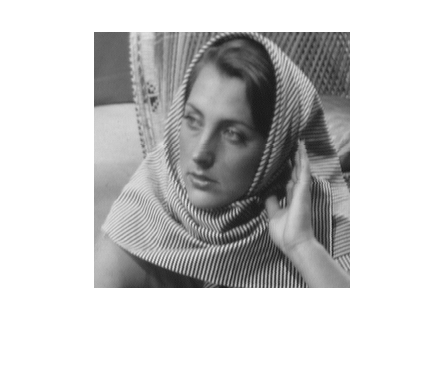

rng(2);
I = double(imread("barbara256.png"));
imshow(I/255);

I_final = double(zeros(256, 256));
I_n = zeros(256, 256);
C = dctmtx(8);
D2 = kron(C,C);
Phi= randn(32, 64);
A = Phi*D2;
alpha = (eigs(A'*A, 1));
for i = 1:249
    for j =1:249
        J = I(i:i+7,j:j+7);
        x = reshape(J', [], 1);
        y = Phi*x; 
        theta_pred = ISTA(y, A, alpha);
        x_reshape1 = dct2(reshape(theta_pred', [8,8])');
        I_final(i:i+7,j:j+7) = I_final(i:i+7,j:j+7)+x_reshape1;
        I_n(i:i+7,j:j+7) = I_n(i:i+7,j:j+7)+1;
        
    end
    
end
% 
I_final_a = min(zeros(256, 256)+255, 2.*(I_final./I_n));
RMSE_1 = norm(I_final_a - I)/norm(I)

RMSE_1 = 0.0788

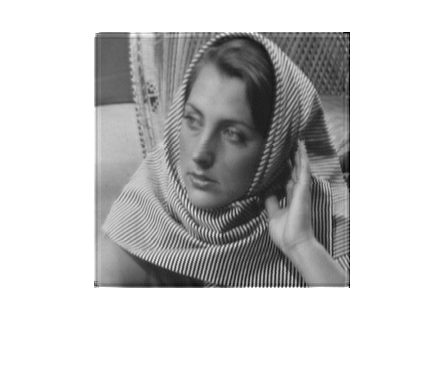

imshow(I_final_a/255);

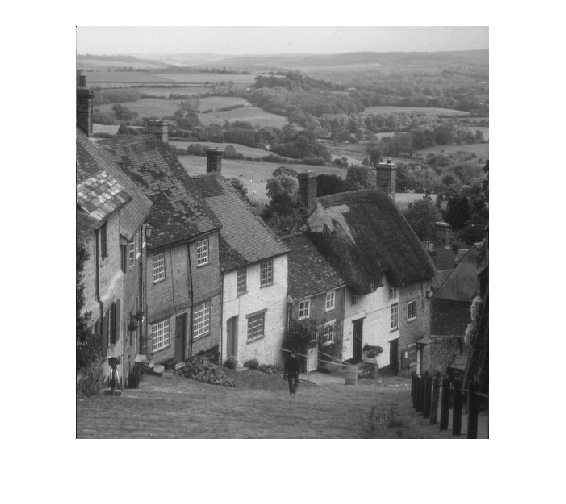


rng(2);
I1 = double(imread("goldhill.png"));
imshow(I1/255);

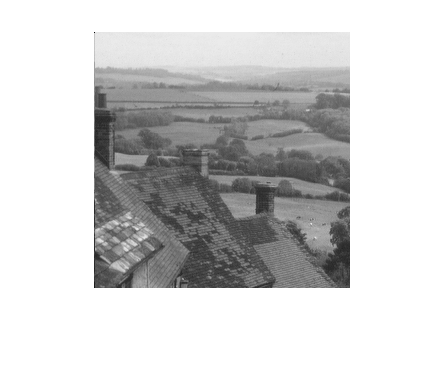

I1 = I1(1:256,1:256);
imshow(I1/255);

I1_final = double(zeros(256, 256));
I1_n = zeros(256, 256);
for i = 1:249
    for j =1:249
        J1 = I1(i:i+7,j:j+7);
        x1 = reshape(J1', [], 1);
        y1 = Phi*x1; 
        theta_pred1 = ISTA(y1, A, alpha);
        x_reshape1 = dct2(reshape(theta_pred1', [8,8])');
        I1_final(i:i+7,j:j+7) = I1_final(i:i+7,j:j+7)+x_reshape1;
        I1_n(i:i+7,j:j+7) = I1_n(i:i+7,j:j+7)+1;
    end
    
end

I1_final_a = min(zeros(256,256)+255,2*I1_final./I1_n);
RMSE1_a = norm(I1_final_a - I1)/norm(I1)

RMSE1_a = 0.0803

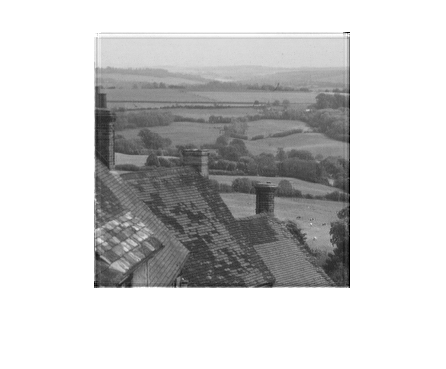

imshow(I1_final_a/255);